clc;
clear;

Wp = 0.2*pi;    % Passband frequency
Ws = 0.3*pi;    % Stopband frequency
Rp = 7;         % Passband ripple (dB)
As = 16;        % Stopband attenuation (dB)

% Order calculation
[N,Wc] = buttord(Wp, Ws, Rp, As, 's');

% Analog Butterworth filter
[b,a] = butter(N, Wc, 's');

% Frequency response
freqs(b,a);
title('Analog Butterworth Lowpass Filter');
grid on;

clc;
clear;

Wp = 0.2*pi;
Ws = 0.3*pi;
Rp = 1;
As = 16;

% Order
[N,Wp] = cheb1ord(Wp, Ws, Rp, As, 's');

% Filter design
[b,a] = cheby1(N, Rp, Wp, 's');

% Frequency response
freqs(b,a);
title('Analog Chebyshev Type-1 Lowpass Filter');
grid on;

clc;
clear;

Wp = 0.2*pi;
Ws = 0.3*pi;
Rp = 1;
As = 15;
T  = 1;

% Convert to analog frequencies
Wp_a = Wp/T;
Ws_a = Ws/T;

% Order
[N,Wc] = buttord(Wp_a, Ws_a, Rp, As, 's');

% Analog filter
[b,a] = butter(N, Wc, 's');

% Impulse invariance transformation
[bd,ad] = impinvar(b,a,1/T);

% Digital frequency response
freqz(bd,ad);
title('Digital Butterworth Filter (Impulse Invariance)');
grid on;

clc;
clear;

Wp = 0.2*pi;
Ws = 0.3*pi;
Rp = 1;
As = 15;
T  = 1;

Wp_a = Wp/T;
Ws_a = Ws/T;

% Order
[N,Wp_a] = cheb1ord(Wp_a, Ws_a, Rp, As, 's');

% Analog filter
[b,a] = cheby1(N, Rp, Wp_a, 's');

% Impulse invariance
[bd,ad] = impinvar(b,a,1/T);

freqz(bd,ad);
title('Digital Chebyshev-I Filter (Impulse Invariance)');
grid on;

clc;
clear;

Wp = 0.2*pi;
Ws = 0.3*pi;
Rp = 1;
As = 15;
T  = 1;

% Prewarping
Wp_a = (2/T)*tan(Wp/2);
Ws_a = (2/T)*tan(Ws/2);

% Order
[N,Wc] = buttord(Wp_a, Ws_a, Rp, As, 's');

% Analog filter
[b,a] = butter(N, Wc, 's');

% Bilinear transform
[bd,ad] = bilinear(b,a,1/T);

freqz(bd,ad);
title('Butterworth Filter using Bilinear Transformation');
grid on;

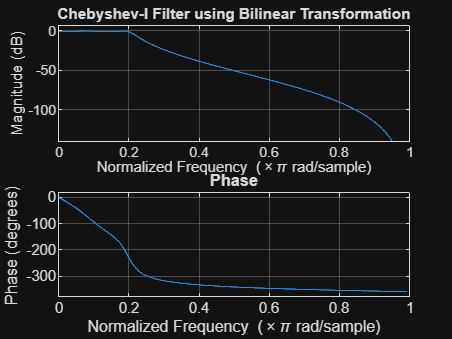

clc;
clear;

Wp = 0.2*pi;
Ws = 0.3*pi;
Rp = 1;
As = 15;
T  = 1;

% Prewarping
Wp_a = (2/T)*tan(Wp/2);
Ws_a = (2/T)*tan(Ws/2);

% Order
[N,Wp_a] = cheb1ord(Wp_a, Ws_a, Rp, As, 's');

% Analog filter
[b,a] = cheby1(N, Rp, Wp_a, 's');

% Bilinear transform
[bd,ad] = bilinear(b,a,1/T);

freqz(bd,ad);
title('Chebyshev-I Filter using Bilinear Transformation');
grid on;